# Hankel-Transform Reconstruction (HTR) Tomography for VMI Data

This MATLAB live script serves as a demonstration and intorudction to HTR tomography. Full details can be found in our publication 'Tomographic Reconstruction Techniques Optimized for Velocity-Map Imaging Applications' ([https://doi.org/10.1063/5.0101789](https://doi.org/10.1063/5.0101789)).

The operating principles of HTR are shown here using simple example distributions. This can be edited to test and demo more complicated distributions as the user wishes. Projections of the simulated distribution are measured my rotating the distribution over a series of angles and integrating over the *x*-pixel coordinate.

The code 'HTR_2D.mat' is used to reconstruct slices in the *xy*-plane using the HTR algorithm.

'HTR_3D.mat' performs 'HTR_2D.mat' at each *z*-location within the projected data set and reconstructs the entire 3D distribution from the set of 2D sinograms.

If you use any of the codes presented here in any published work, we (Chris Sparling and Dave Townsend) expect to be acknowedged for providing this to you and we ask that you also cite the original publication.

Good luck!

Chris Sparling, 03/11/2022

## -- Make a test distribution --

res = 256; % resolution of test data

x = linspace(-1,1,res); % generate coordinate system

[X, Y, Z] = meshgrid(x,x,x);

R = sqrt(X.^2 + Y.^2 + Z.^2);

COST = Z./R;

SINT = Y./R;

P2 = 0.5*(3*COST.^2 - 1); % 2nd order Legendre polynomial (used to define annistropy - can use any other functions!)

I = exp(-((R-0.7)/0.05).^2).*(1 + 2*P2); % generate a simulated distribution (single photon ionization, cylindrically symmetric - good starting point!)

%I = exp(-((R-0.7)/0.05).^2).*(COST.^2.*SINT.^2); % More complicated distribution with no cylindrical symmetry

I = I/max(I(:));

% Display distribtion and planar cuts

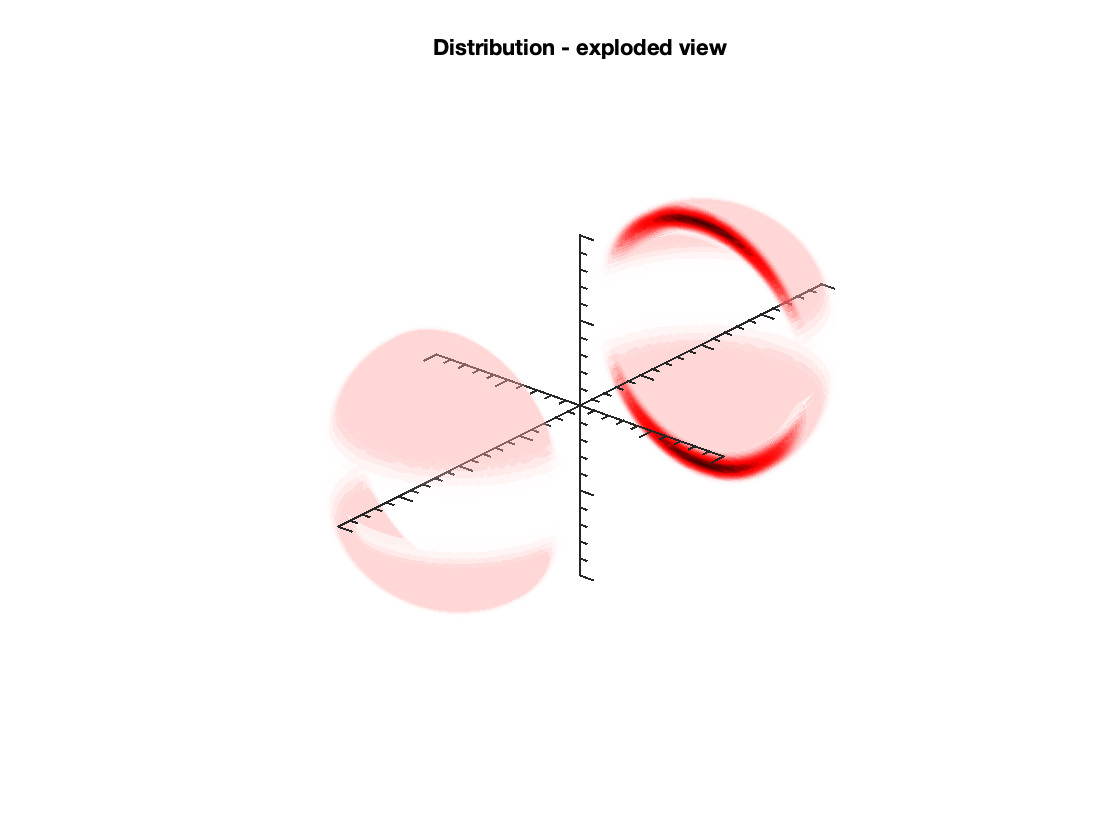


figure
VMIisosurf(I,1,'split')
title('Distribution - exploded view')

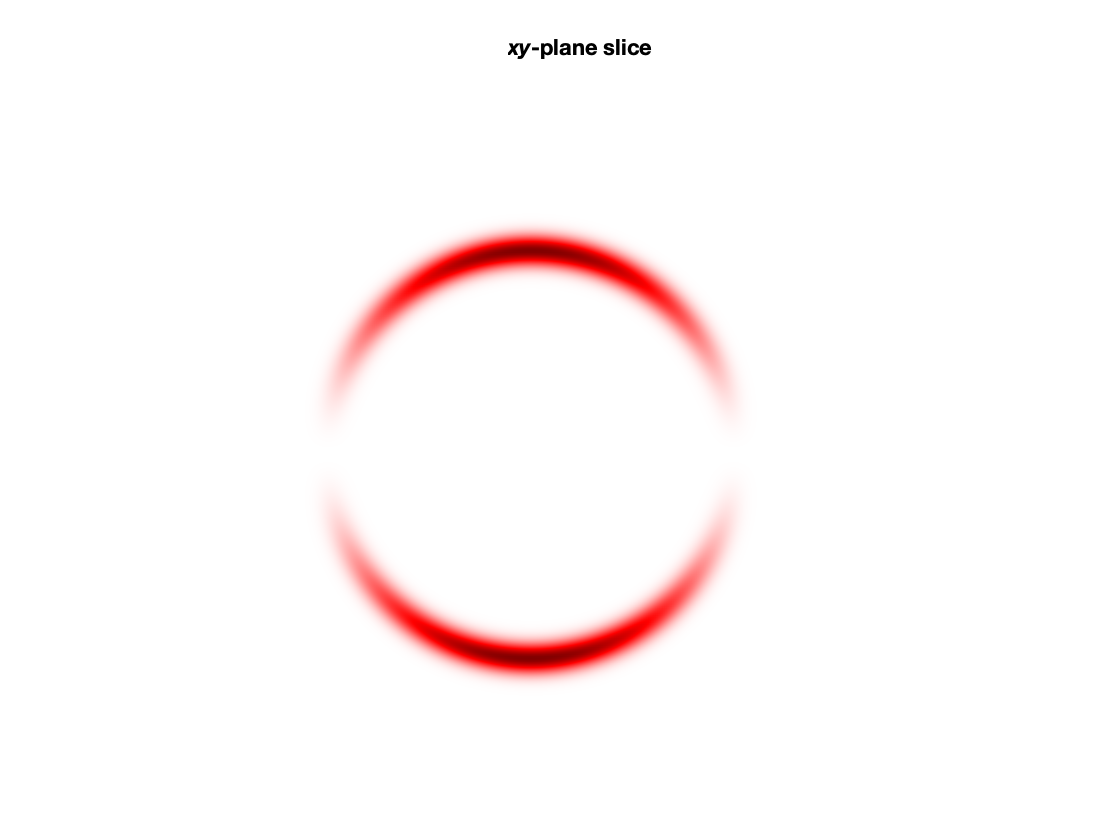



figure
showim(squeeze(I(res/2,:,:))',1)
title('{\itxy\it}-plane slice')
caxis([-1 1])

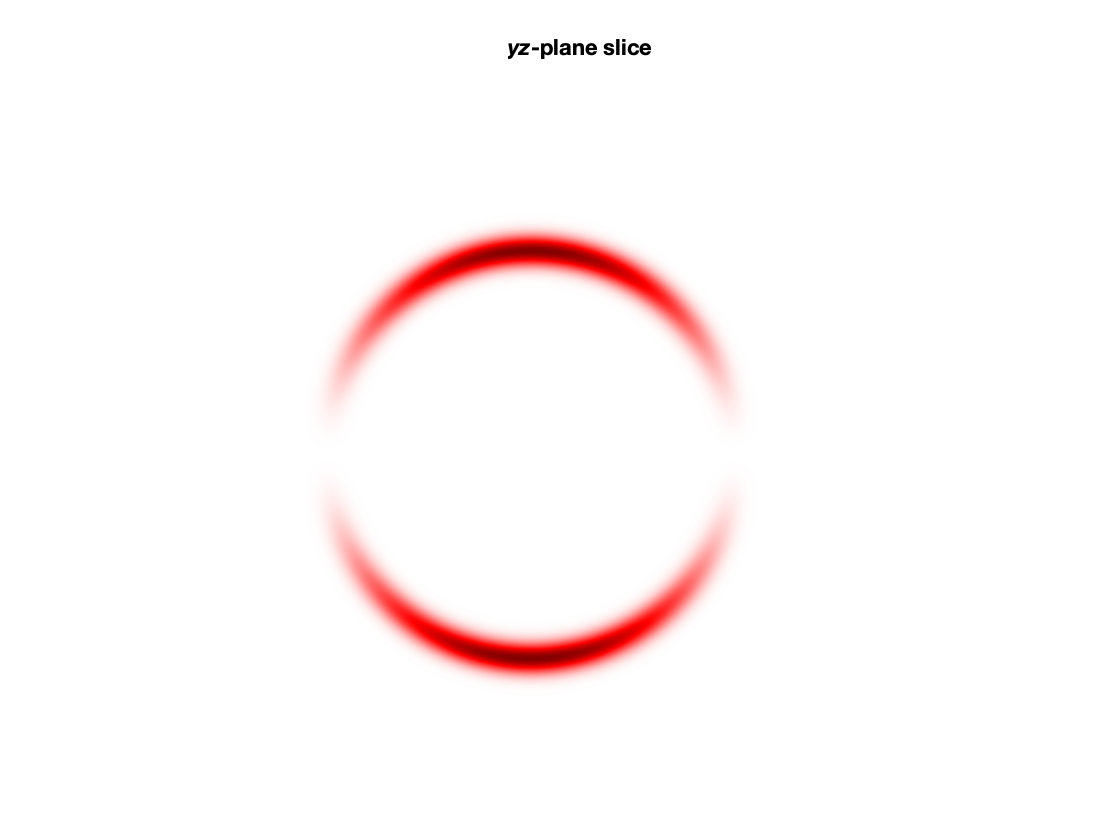



figure
showim(squeeze(I(:,res/2,:))',1)
title('{\ityz\it}-plane slice')
caxis([-1 1])

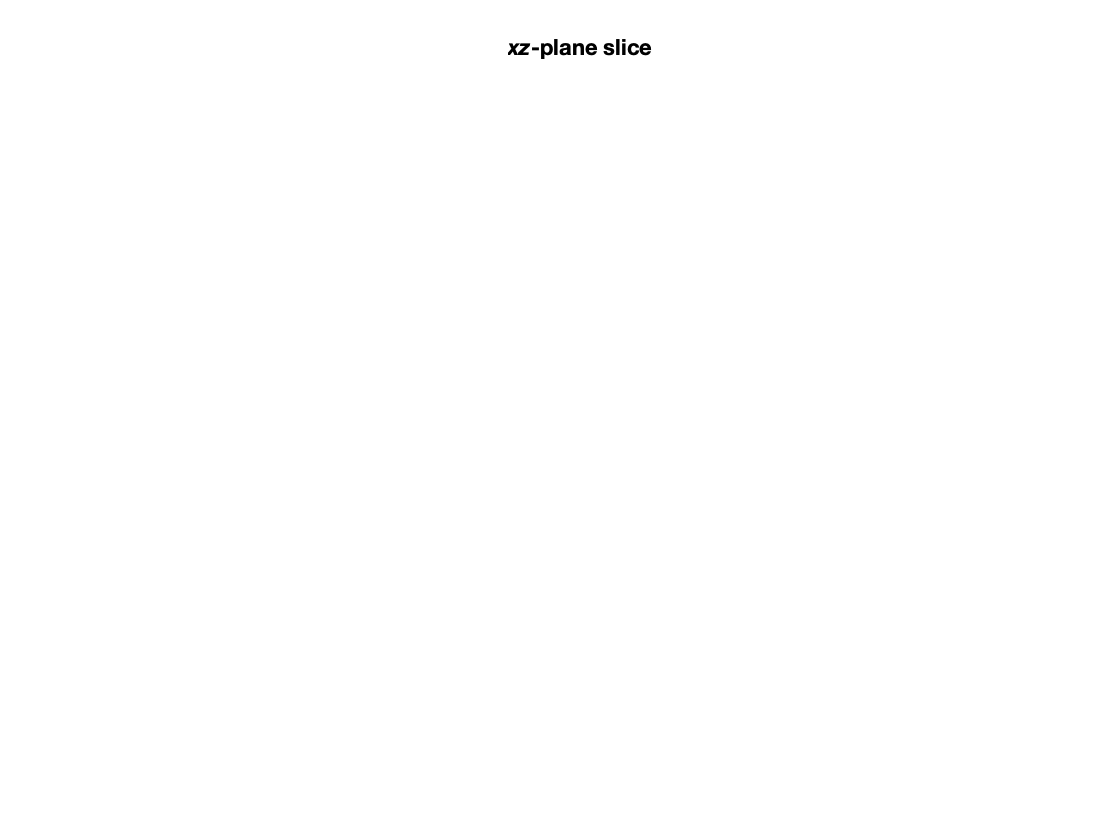


figure
showim(squeeze(I(:,:,res/2))',1)
title('{\itxz\it}-plane slice')
caxis([-1 1])

## -- Record tomographic projections --

% Simulate some projections between 0º and 180º

% You do not need a projection at both 0º and 180º - this will not Fourier transform correctly later!

n_projections = 18;

step_size = 180/n_projections;

angles = [0:step_size:180];

P = zeros([res, res, n_projections]);

for idx = 1:n_projections
    
    an = angles(1,idx);
    
    P(:,:,idx) = squeeze(sum(imrotate3(I,an,[0 1 0],'cubic','crop'),2))';
    
end


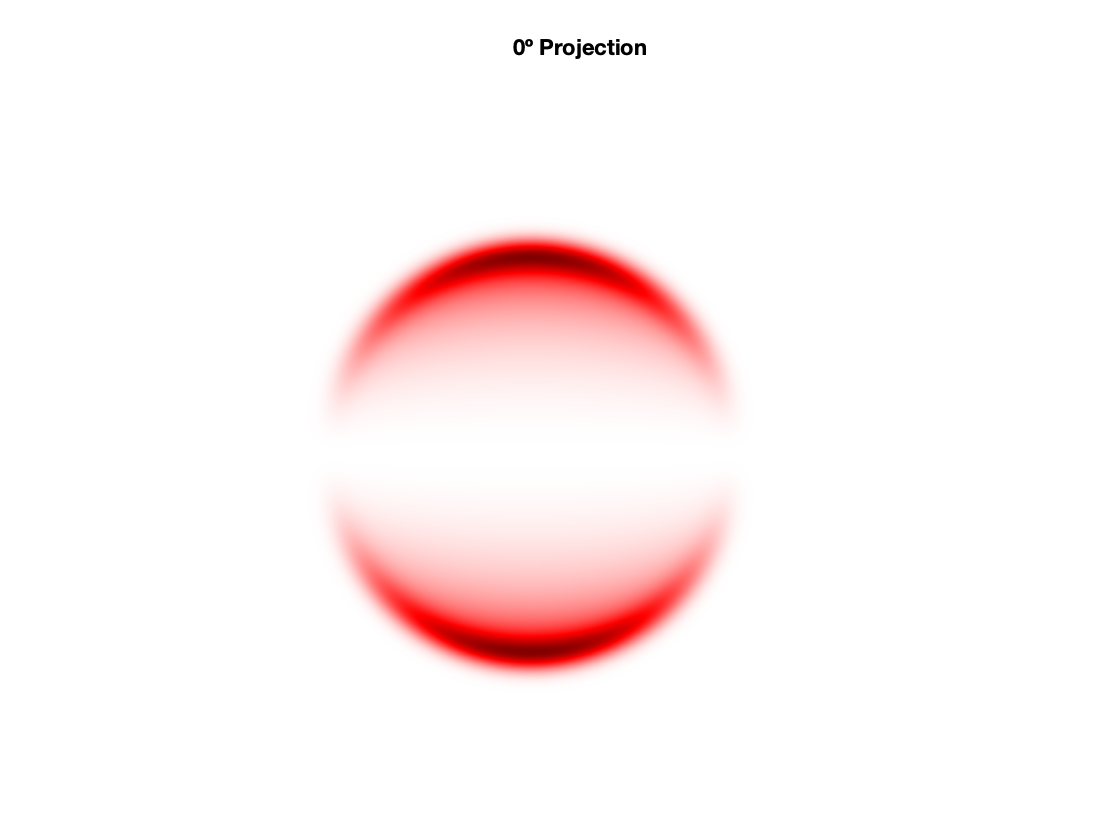

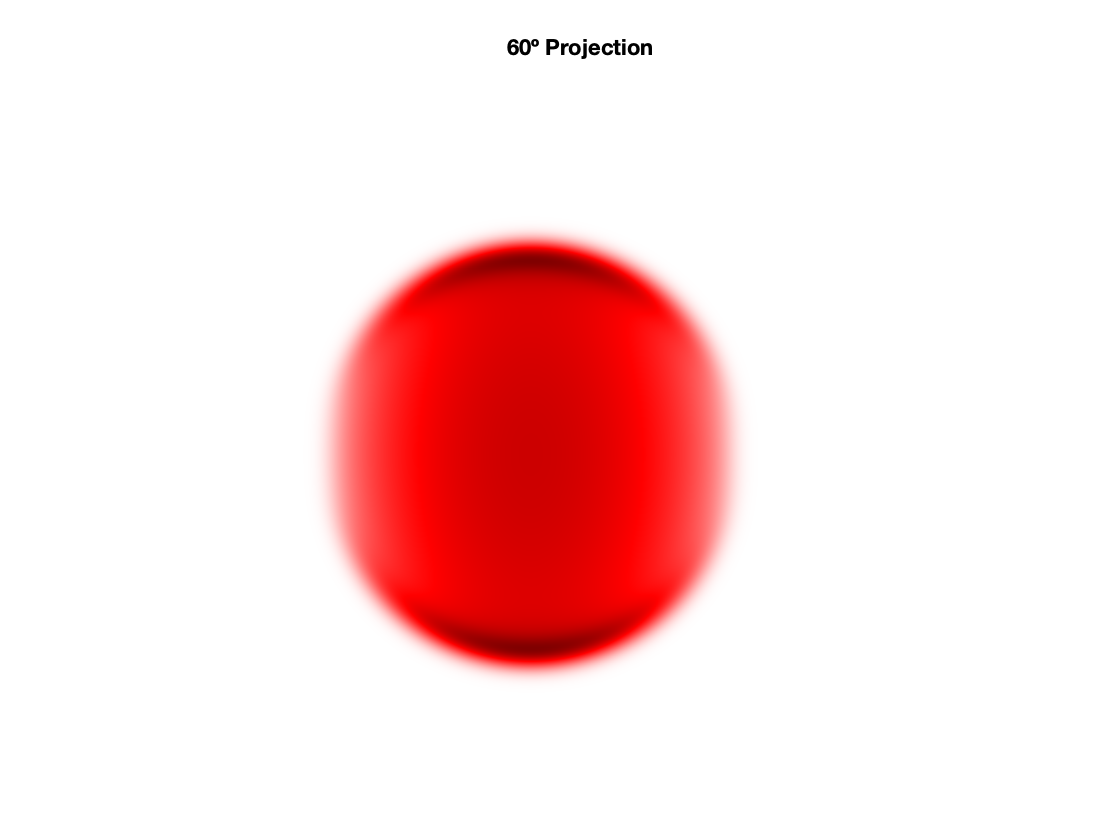

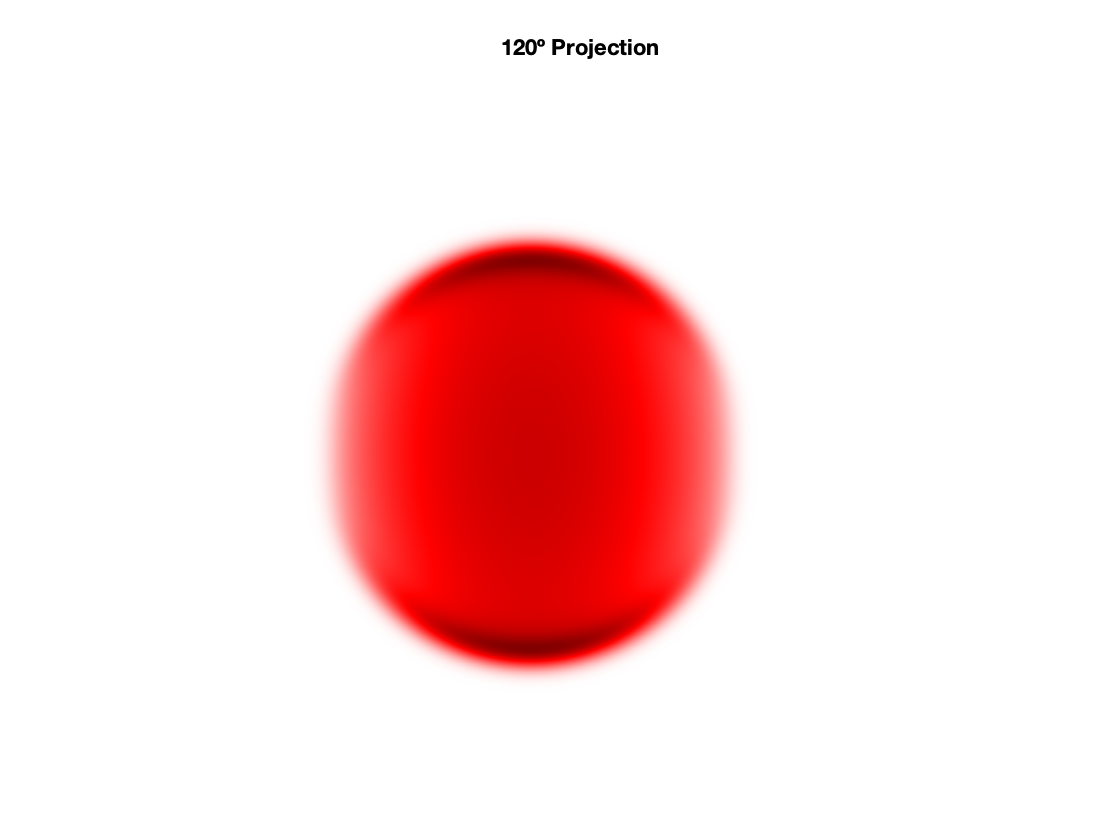


% Display some of the projections

for idx = 1:6:n_projections
    
    an = angles(1,idx);
    
    figure
    showim(P(:,:,idx),1)
    title(strcat(num2str(an),'º Projection'))
    
end

## -- Analyse the sinogram of the centre sice -- 

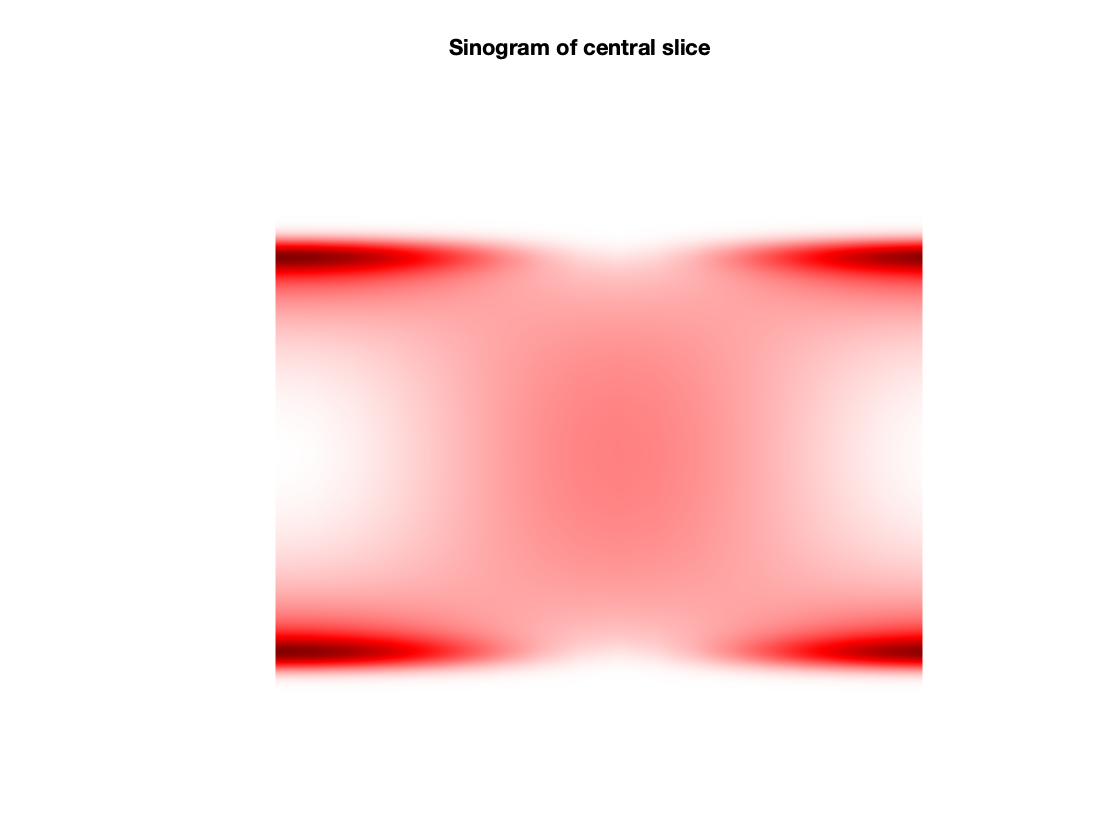

% Extract the sinogrma of the centre line of pixels

sinogram = squeeze(P(:,res/2,:));

figure
showim(sinogram,1)
title('Sinogram of central slice')

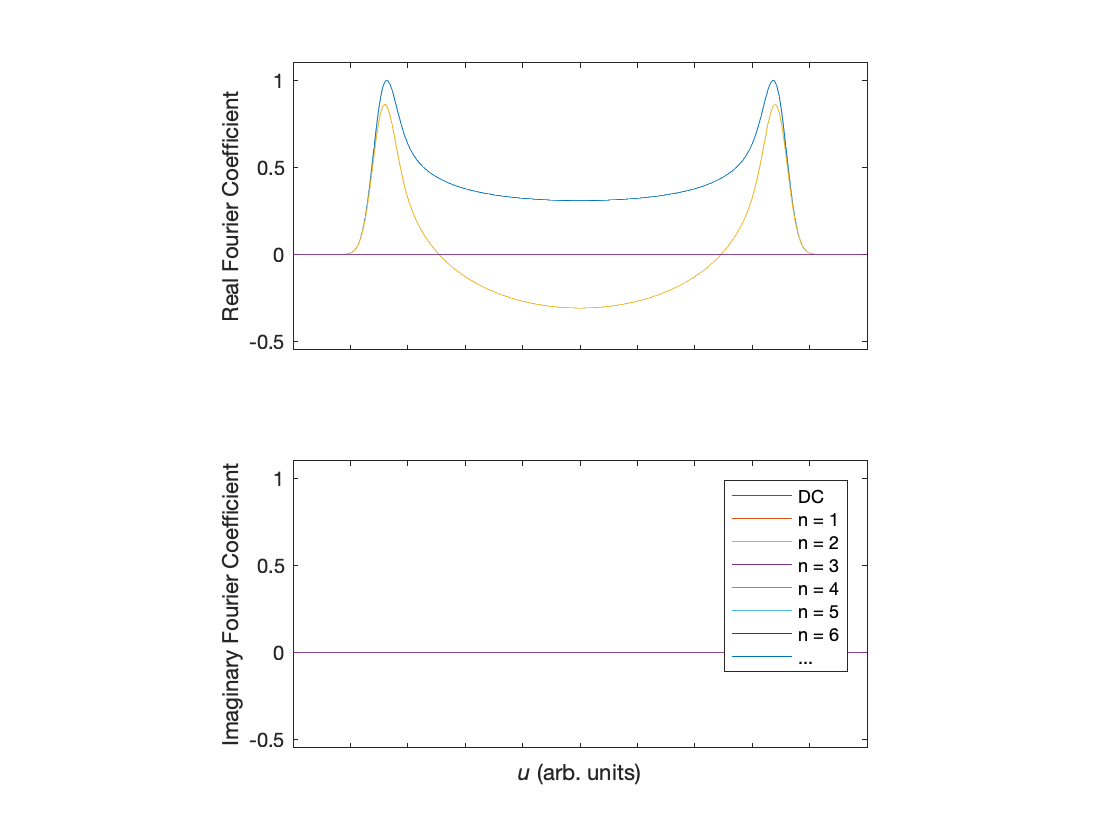


% Fourier transform the sinogram

F = fft([sinogram, flipud(sinogram)],[],2);

F(:,1) = F(:,1)/2;

F = F(:,1:size(F,2)/2);

F = F./max(abs(F(:)));

figure
subplot(2,1,1)
plot(x,real(F))
xticklabels([])
ylim(1.1*[-0.5 1])
ylabel('Real Fourier Coefficient')
pbaspect([2 1 1])

subplot(2,1,2)
plot(x,imag(F))
xticklabels([])
xlabel('{\itu\it} (arb. units)')
ylim(1.1*[-0.5 1])
ylabel('Imaginary Fourier Coefficient')
pbaspect([2 1 1])
legend({'DC','n = 1','n = 2','n = 3','n = 4','n = 5','n = 6','...'})

Only frequncies that appear in the original angular distribution appear in the sinogram!

Therefore, the number of projections required to make a tomographic measurment in VMI experiments depends on the form of the distribution being recorded. This is a significant benefit of HTR over other reconstruction approaches.

As a good rule, an N photon process will require at least 2N + 1 projections. Other projections will not contribute meaningfully to the sinogram. If using FBP, SIRT *etc. *around a minimum of 50 projections are required to reconstruct even the simplest perfectly spherical distribution!

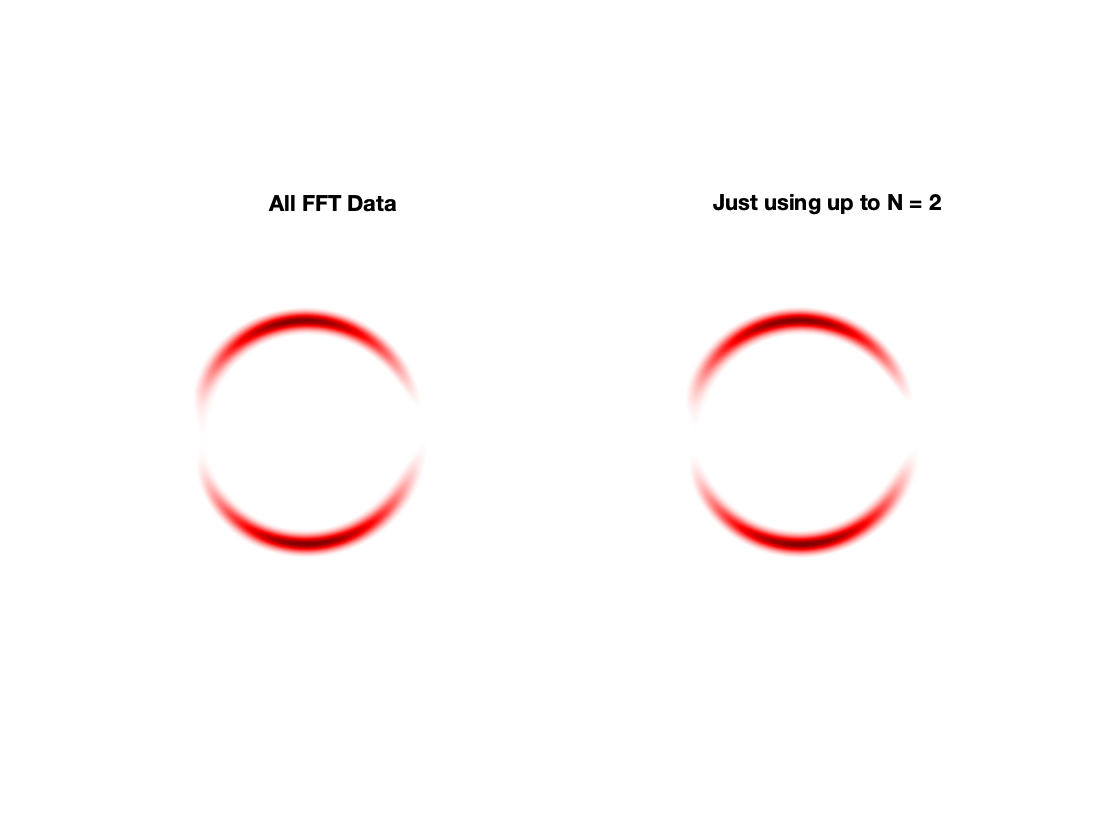


N = size(sinogram,2); % using all the data

slice_reconstruction_1 = HTR_2D(sinogram,N);

figure
subplot(1,2,1)
showim(slice_reconstruction_1,1)
title('All FFT Data')

N = 2; % using the minimum sampling condition

slice_reconstruction_1 = HTR_2D(sinogram,N);

subplot(1,2,2)
showim(slice_reconstruction_1,1)
title('Just using up to N = 2')

## -- Full 3D reconstruction --

% same analysis as before, but now the full 3D-distribution!

N = size(sinogram,2);

I_reconstructed = HTR_3D(P,N);

Done in 53.6233 seconds!


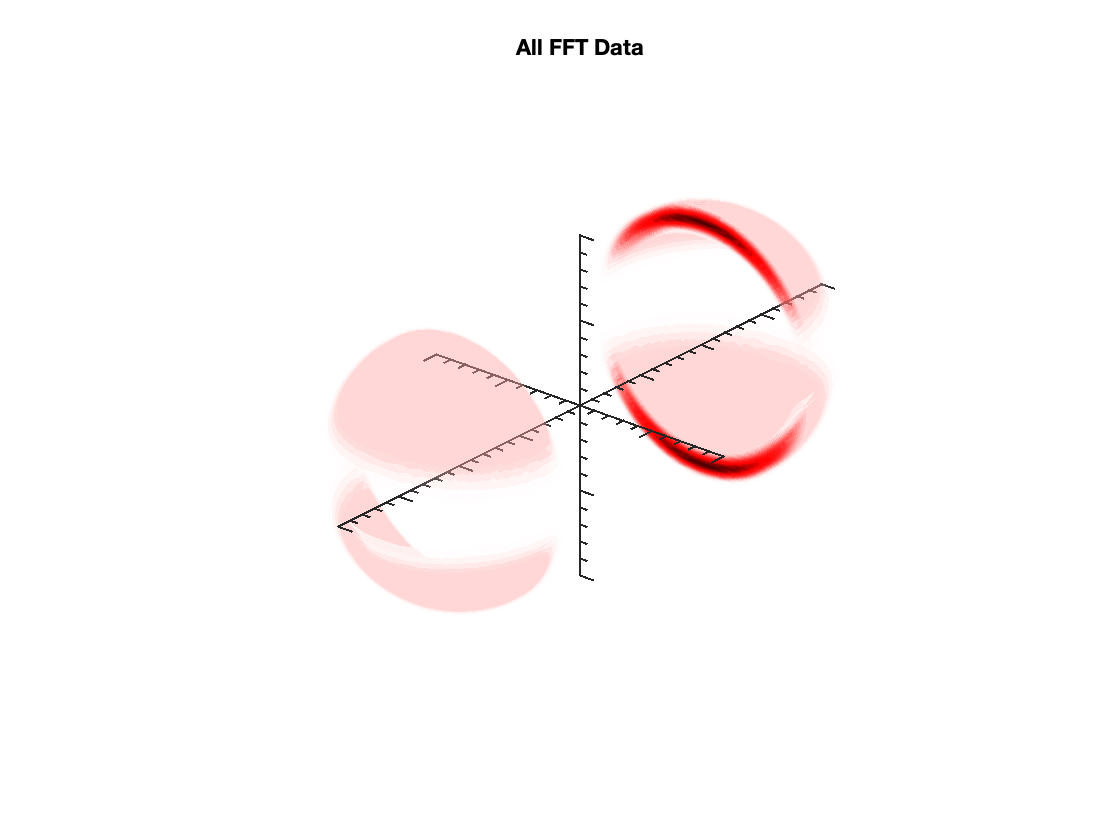



figure
VMIisosurf(I_reconstructed,1,'split')
title('All FFT Data')


N = 2;

I_reconstructed = HTR_3D(P,N);

Done in 5.4476 seconds!


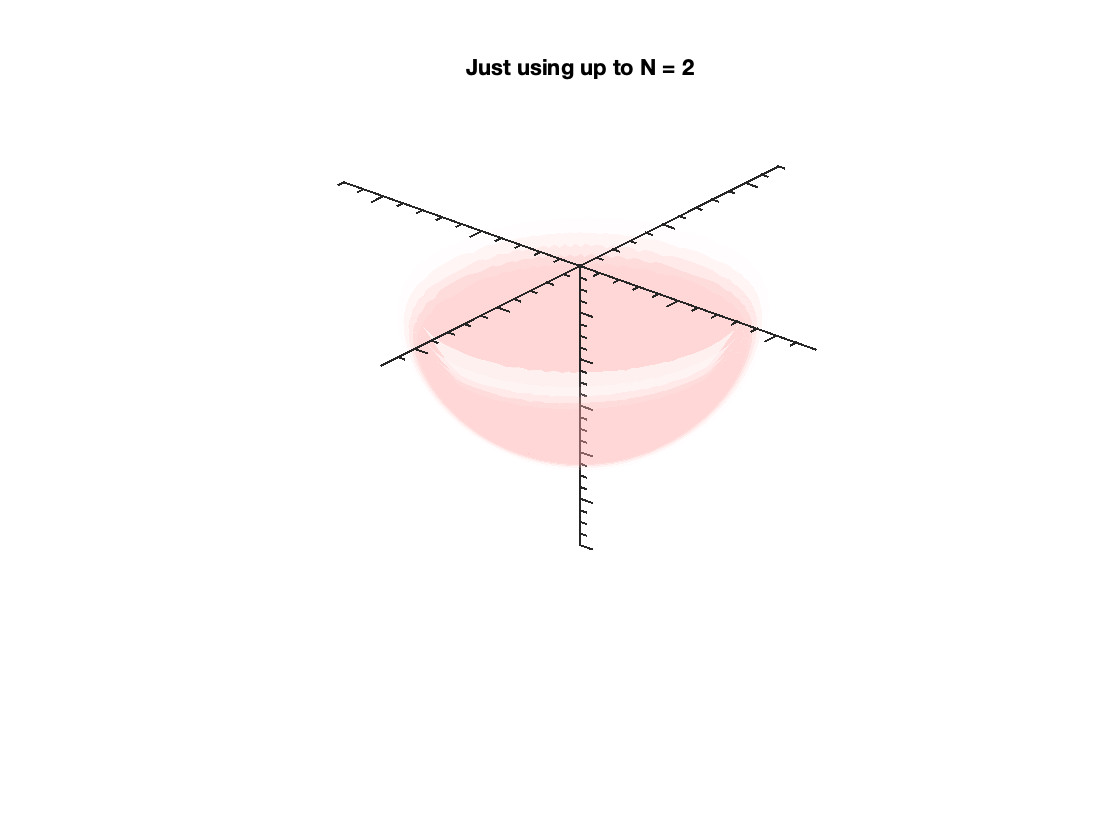


figure
VMIisosurf(I_reconstructed,1,'split')
title('Just using up to N = 2')